# PID Control

In the previous attempt ('OnOffControl.mlx') we used ON/OFF conttrol strategy, which resulted in a pulsating output for the temperature, this could eliminated by implementing different control strategy, such as PID control.

### P Control

The proportional controller (P Controller) is mathematically expressed as $\textrm{control}=K_p \times \textrm{error}$. In the system, we cannot modulate the intensity of the temperature, it is either connected to the source or not. We can, however, approximate a continuous P control strategy by using PWM, The "intensity" of the control is affected by changing the percent of time the input is "on" over the time of one period. This percentage is called the "*Duty Cycle*".

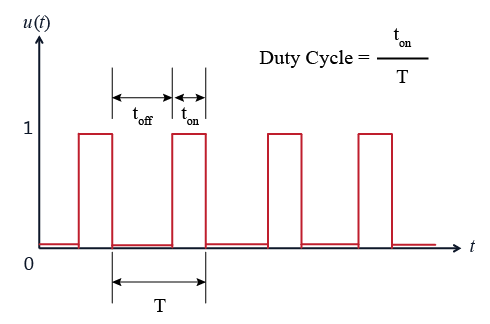

#### Calculating Proportional Gain Kp

The model derived earlier for the system was as follows:


$$P\left(s\right)=\frac{\Delta T\left(s\right)}{D\left(s\right)}=\frac{174\ldotp 7}{52\ldotp 4s+1}\;\textrm{°C}$$


An idealized representation for the system with the controller would be like this:

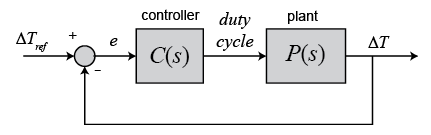

For this system, and using the P controller, the system closed-loop transfer function could be derived as follows:


$$\begin{array}{l}
C\left(s\right)=K_p \\
G_{\textrm{cl}} \left(s\right)=\frac{C\left(s\right)P\left(s\right)}{1+C\left(s\right)P\left(s\right)}=\frac{174\ldotp 7K_p }{52\ldotp 4s+1+174\ldotp 7K_p }
\end{array}$$


From the transfer function, we can conclude has a DC gain of:


$$G_{\textrm{cl}} \left(0\right)=\frac{174\ldotp 7K_p }{1+174\ldotp 7K_p }$$


#### Analyzing Simulation Data

As observed before from the plant transfer function, the time constant is very large, hence, to get a faster response from the system (for expermintal purposes) the proportional gain is chosen to be 100. $K_p =100$

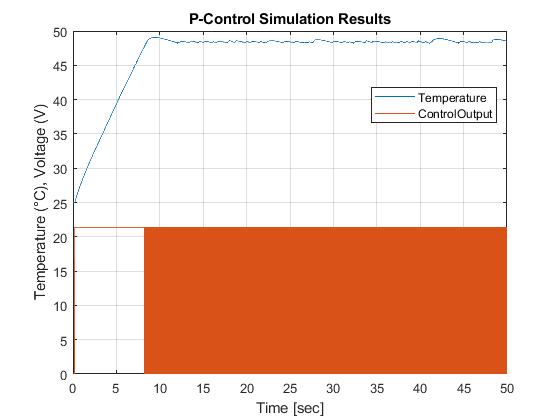

clear,clc,close all;
% read simulation data into a table
simData = readtable('C:\Users\engin\Desktop\PID_TeC\ControllerDesign\P_Controller\PControl_SIMData.DAT');
% change column names for something easy to use
simData.Properties.VariableNames = {'Time','Tov','Control'};
V_step = 0.025;
% plot results
% multiply the temperature data by (1/V_step) to convert to °C
plot(simData.Time,simData.Tov*(1/V_step)); 
hold on
% the control output is scaled by 5 to make the figure easier to read
plot(simData.Time,simData.Control*5);
grid on; xlabel('Time [sec]'); ylabel('Temperature (°C), Voltage (V)');
title('P-Control Simulation Results')
legend('Temperature','ControlOutput','Location',"best");
hold off;

From the system behavior, we can conclude the following:

- The system settling time is around 7~8 seconds

- The system does not reach the desired setpoint with proportional gain 100 $K_p =100$

### PI Control

Adding an integral term to the controller gives the term PI-Controller "*Propotional-Integral Controller*", the PI-Controller has the form of:


$$C\left(s\right)=K_p +\frac{K_i }{s}$$


Adding the controller to the system, the transfer function can be derived as:


$$G_{\textrm{cl}} \left(s\right)=\frac{C\left(s\right)P\left(s\right)}{1+C\left(s\right)P\left(s\right)}=\frac{174\ldotp 7\left(K_p s+K_i \right)}{52\ldotp 4s^2 +\left(1+174\ldotp 7K_p \right)s+174\ldotp 7K_i }$$


#### Analyzing Simulation Data

As observed before from the plant transfer function, the time constant is very large, hence, to get a faster response from the system (for expermintal purposes) the proportional gain is chosen to be 100, and the Intergral gain is 2. $K_p =100\;,K_i =2$

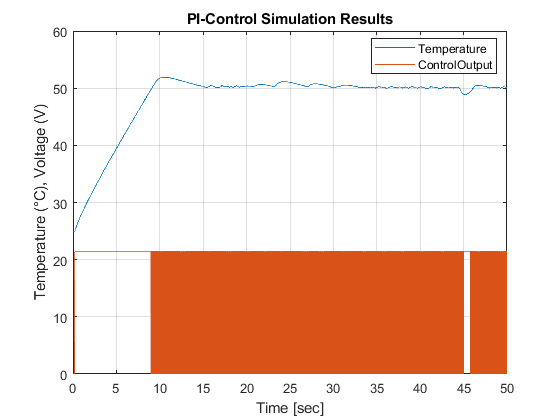

clear,clc;
% read simulation data into a table
simData = readtable('C:\Users\engin\Desktop\PID_TeC\ControllerDesign\PI_Controller\PIControl_SIMData.DAT');
% change column names for something easy to use
simData.Properties.VariableNames = {'Time','Tov','Control'};
V_step = 0.025;
% plot results
% multiply the temperature data by (1/V_step) to convert to °C
plot(simData.Time,simData.Tov*(1/V_step)); 
hold on
% the control output is scaled by 5 to make the figure easier to read
plot(simData.Time,simData.Control*5);
grid on; xlabel('Time [sec]'); ylabel('Temperature (°C), Voltage (V)');
title('PI-Control Simulation Results')
legend('Temperature','ControlOutput','Location',"best");
hold off;

### Further analysis

For expermintal purposes, we add a derivative term to the controller and observe the results.


$$K_p =50,K_i =2,K_d =0\ldotp 1$$


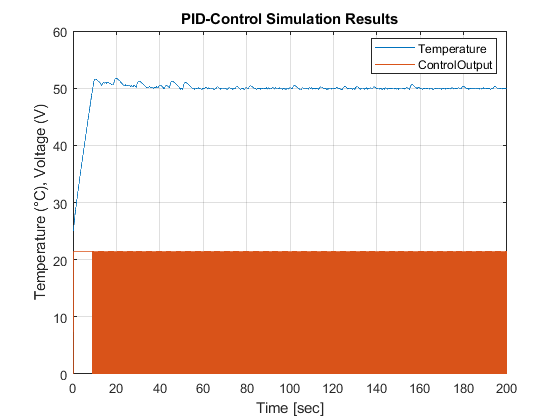

clear,clc;
% read simulation data into a table
simData = readtable('C:\Users\engin\Desktop\PID_TeC\ControllerDesign\PID_Controller\PIDControl_SIMData.DAT');
% change column names for something easy to use
simData.Properties.VariableNames = {'Time','Tov','Control'};
V_step = 0.025;
% plot results
% multiply the temperature data by (1/V_step) to convert to °C
plot(simData.Time,simData.Tov*(1/V_step)); 
hold on
% the control output is scaled by 5 to make the figure easier to read
plot(simData.Time,simData.Control*5);
grid on; xlabel('Time [sec]'); ylabel('Temperature (°C), Voltage (V)');
title('PID-Control Simulation Results')
legend('Temperature','ControlOutput','Location',"best");
hold off;

### Conclusion

After implmenting different control stratigies we can conclude the following:

- Using a proportional-only controller will give an output according to the value of the P-gain, $K_p$, the more the P-gain, the more the system will osciliate and overshoot.

- More control over the system behavior can be acheived using a proportional-integral controller. Proper tuning of proportional and integral gains, $K_p ,K_i$, can result in the required value of the steady-state error. However, the controller might have a tradeoff between the desired steady-state error, and other characteristics (Rise time, Settling time, and Overshoot).

- The desired steady-state error and system behavior can be acheived using a PID controller (Proportional-Integral-Derivative). With proper tuning, the system can acheive the desired behavior.

NOTE: Tunning is best to be made with the hardware available.